root1 = fzero(@pjh_21010954_func_1, [0 1]);
root2 = fzero(@pjh_21010954_func_1, [1 3]);
roots = [root1, root2]

roots =          0    1.3606



min_x = fminbnd(@pjh_21010954_func_1,0,4);
min_y = pjh_21010954_func_1(min_x)

min_y = -0.7757

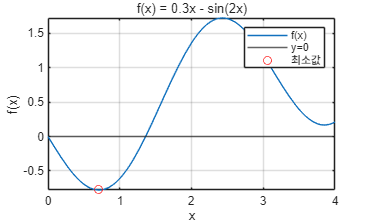


fplot(@pjh_21010954_func_1,[0 4])
hold on
yline(0)
plot(min_x, min_y, 'ro')
grid on
title('f(x) = 0.3x - sin(2x)')
xlabel('x')
ylabel('f(x)')
legend('f(x)', 'y=0', '최소값')
hold off

h = 100;
v0 = 50;
g = 9.81;
[t1,t2] = pjh_21010954_func_2(h,v0,g)

t1 = 7.4612

t2 = 2.7324

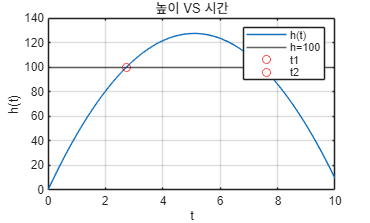

t = 0:0.01:10;
h_t = v0*t-0.5*g*t.^2;

plot(t,h_t)
hold on
yline(h)
plot(t1, h, 'ro')
plot(t2, h, 'ro')
grid on
xlabel('t')
ylabel('h(t)')
title('높이 VS 시간')
legend('h(t)', 'h=100', 't1', 't2')
hold off

global V;
V = 10;
r = fminbnd(@pjh_21010954_func_3b,0.1,10)

r = 1.8901

h2 = (3.*V)./(pi.*r.^2)

h2 = 2.6730

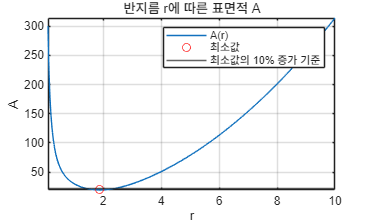

A_min = pjh_21010954_func_3b(r);

fplot(@pjh_21010954_func_3b,[0.1 10])
hold on
plot(r, A_min, 'ro')
yline(1.1*A_min)
grid on
xlabel('r')
ylabel('A')
title('반지름 r에 따른 표면적 A')
legend('A(r)', '최소값', '최소값의 10% 증가 기준')
hold off


f = @(r) (pjh_21010954_func_3b(r)-1.1*A_min);
R1 = fzero(f,[0.1 1.8]);
R2 = fzero(f,[2.2 4]);
r_left = r - R1

r_left = 0.4078

r_right = R2 - r

r_right = 0.4415

r_range = [R1 R2]

r_range =     1.4823    2.3316


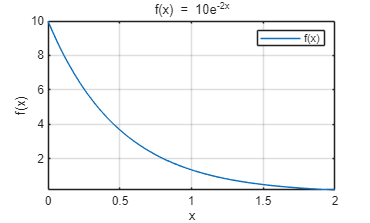

f2 = @(x) (10.*exp(-2*x));
fplot(f2,[0 2])
xlabel('x')
ylabel('f(x)')
title('f(x) = 10e^{-2x}')
grid on
legend('f(x)')

f3 = @(x) (30.*x.^2 - 300.*x + 4);

fplot(f3,[0 10])
grid on
xlabel('x')
ylabel('f(x)')
title('f(x) = 30x^2 - 300x + 4')

hold on
min_x2 = fminbnd(f3,4,6)

min_x2 = 5.0000

min_y2 = f3(min_x2)

min_y2 = -746.0000

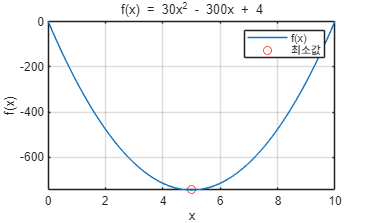

plot(min_x2,min_y2, 'ro')
legend('f(x)', '최소값')
hold off

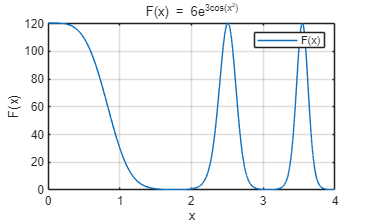

f4 = @(x) (x.^2);
g2 = @(y) (3.*cos(y));
h3 = @(z) (6.*exp(z));
F = @(x) h3(g2(f4(x)));
fplot(F, [0 4])
grid on
xlabel('x')
ylabel('F(x)')
title('F(x) = 6e^{3cos(x^2)}')
legend('F(x)')